code adapted from: https://www.mathworks.com/help/vision/ug/image-category-classification-using-deep-learning.html

clc; clear;

Download images from computer

downloadFolder = tempdir;
%change the following line to your image location
imageFolder='\\client\c$\Users\allis\Documents\Comp Apps\Final Project\brain_tumor_dataset'

imageFolder = '\\client\c$\Users\allis\Documents\Comp Apps\Final Project\brain_tumor_dataset'

imds = imageDatastore(imageFolder, 'LabelSource', 'foldernames', 'IncludeSubfolders',true);


Determine the smallest amount of images in a category

tbl = countEachLabel(imds);
minSetCount = min(tbl{:,2});

Use splitEachLabel method to trim the set.

imds = splitEachLabel(imds, minSetCount, 'randomize');

Load pretrained network resnet-50

net = resnet50();

Split 30% of the data into the training set and 70% into the testing set

[trainingSet, testSet] = splitEachLabel(imds, 0.3, 'randomize');

resize images into the size needed by resnet50 and create augmented data sets for training and testing

imageSize = net.Layers(1).InputSize;
augmentedTrainingSet = augmentedImageDatastore(imageSize, trainingSet, 'ColorPreprocessing', 'gray2rgb');
augmentedTestSet = augmentedImageDatastore(imageSize, testSet, 'ColorPreprocessing', 'gray2rgb');

Extract training features from the layer named 'fc1000'

featureLayer = 'fc1000';
trainingFeatures = activations(net, augmentedTrainingSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

Get training labels from the trainingSet

trainingLabels = trainingSet.Labels;

Use the Convolutional Neural Network image features to train a multiclass SVM classifier. A fast Stochastic Gradient Descent solver is used for training

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding |       Lambda |      Learner |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.18966 |     0.65822 |     0.18966 |     0.18966 |     onevsall |    7.018e-07 |          svm |
|    2 | Accept |     0.24138 |     0.26001 |     0.18966 |     0.21551 |     onevsone |   1.8523e-05 |          svm |
|    3 | Accept |     0.44828 |     0.41038 |     0.18966 |     0.18972 |     onevsone |       23.161 |     logistic |
|    4 | Best   |     0.17241 |     0.46299 |     0.17241 |     0.18078 |     onevsall |       1.8553 |          svm |
|    5 | Accept |     0.43103 |     0.34002 |   

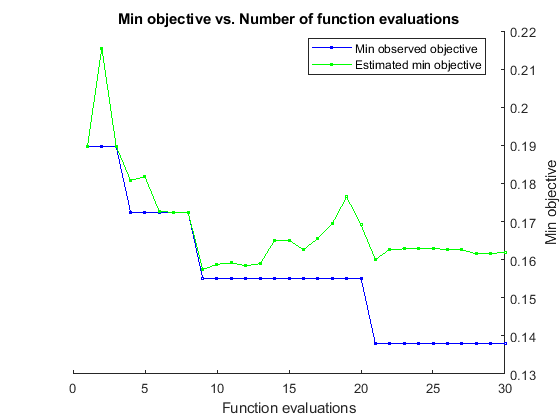


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 52.1247 seconds
Total objective function evaluation time: 11.8096

Best observed feasible point:
     Coding      Lambda     Learner
    ________    ________    _______

    onevsone    0.072691      svm  

Observed objective function value = 0.13793
Estimated objective function value = 0.16197
Function evaluation time = 0.43635

Best estimated feasible point (according to models):
     Coding      Lambda     Learner
    ________    ________    _______

    onevsone    0.076035      svm  

Estimated objective function value = 0.16191
Estimated function evaluation time = 0.45738



classifier = fitcecoc(trainingFeatures, trainingLabels, ...
    'Learners', 'Linear', 'Coding', 'onevsall', 'ObservationsIn', 'columns','OptimizeHyperparameters','auto');

 Extract test features using the CNN

testFeatures = activations(net, augmentedTestSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

 Pass CNN test image features to trained classifier

predictedLabels = predict(classifier, testFeatures, 'ObservationsIn', 'columns');

Get the known labels

testLabels = testSet.Labels;

Tabulate the results using a confusion matrix.

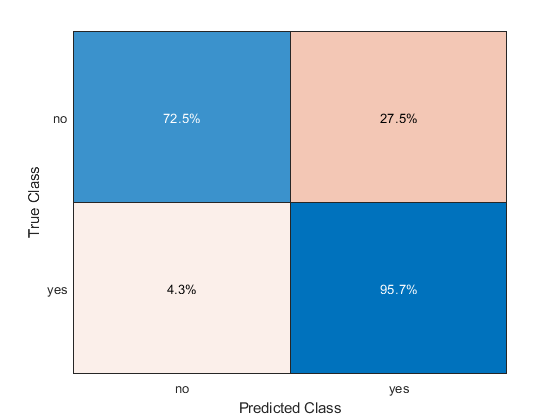

confMat = confusionmat(testLabels, predictedLabels);
confusionchart(testLabels, predictedLabels,'Normalization', 'row-normalized')

Convert confusion matrix into percentage form

confMat = bsxfun(@rdivide,confMat,sum(confMat,2))

confMat =     0.7246    0.2754
    0.0435    0.9565


 Display the mean accuracy

accuracy=mean(diag(confMat))

accuracy = 0.8406

fprintf('The accuracy of resnet-50 in classifying MRI imagis is: %f', accuracy)

The accuracy of resnet-50 in classifying MRI imagis is: 0.840580